# Pulse arrival time uncertainty propagation

Copyright (C) [2020](#2020)  [Bolic](#Miodrag)

  This program is free software: you can redistribute it and/or modify   it under the terms of the GNU General Public License as published by  the Free Software Foundation, either version 3 of the License, or  (at your option) any later version.  This program is distributed in the hope that it will be useful, but WITHOUT ANY WARRANTY; without even the implied warranty of MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE.  See the GNU General Public License for more details <https://www.gnu.org/licenses/>. 

This code was developed by Miodrag Bolic for the book PERVASIVE CARDIAC AND RESPIRATORY MONITORING DEVICES.

### Acknowledgements: 

Uncertainty propagations is based on the code: Joe Klebba (2021). Uncertainty Propagation Functions (https://www.mathworks.com/matlabcentral/fileexchange/89812-uncertainty-propagation-functions), MATLAB Central File Exchange. Retrieved May 19, 2021

## Fitting PAT vs systolic data 

Fitting is done based on regression SBP=a*ln(PAT)+b

Let us assume that the physiological signals used to obtain PAT values are sampled at 250 Hz which means that the sampling period is 4 ms. We will present the error in timing using uniform distribution in the range from -0.002s to 0.002s.

close all
clear all
fprintf('\nExample: PAT\n')


Example: PAT


load('patsbp.mat')

fo = fitoptions('Method','NonlinearLeastSquares',...
               'Lower',[-100,0],...
               'Upper',[-80,inf],...
               'StartPoint',[-90 18]);
linearfittype = fittype({'log(x)','1'},'options',fo);
fit_res = fit(patsbp.PAT,patsbp.SBP,linearfittype)

fit_res =      Linear model:
     fit_res(x) = a*log(x) + b
     Coefficients (with 95% confidence bounds):
       a =      -95.74  (-111.3, -80.2)
       b =        17.7  (2.168, 33.23)

ci = confint(fit_res,0.67); 
std_a=abs(ci(1,1)-fit_res.a) % obtain standard deviation for parameter a

std_a = 7.7091

std_b=abs(ci(2,2)-fit_res.b) % obtain standard deviation for parameter b

std_b = 7.7073

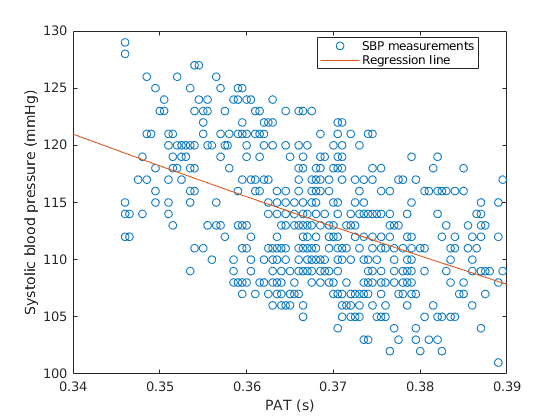


figure
plot(patsbp.PAT,patsbp.SBP,'o')
xlabel("PAT (s)")
ylabel("Systolic blood pressure (mmHg)")
hold on
i=0.34:0.01:0.39;
plot(i,fit_res(i))
legend({'SBP measurements', 'Regression line'},'Location','Best')

## Defining the uncertainties of the parameters

PAT=0.375; 
b=fit_res.b; ub=std_b; % these values are obtained after fitting
a=fit_res.a; ua=std_a; % these values are obtained after fitting
f = @(a,b,x)a.*log(x)+b;
n=100000;
    PAT_data=PAT*ones(n,1)+unifrnd(-0.002,0.002,n,1)-unifrnd(-0.002,0.002,n,1);

## Performing uncertainty propagation

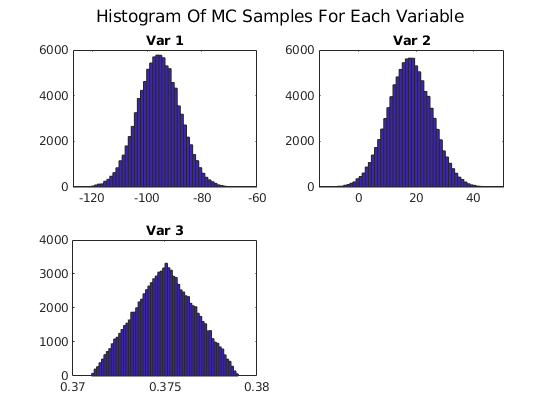

[CI,valMC]=propUncertMC(f,{{a ua};{b,ub};{'Custom',PAT_data}},n,'mean','varHist',60,'hist',60);

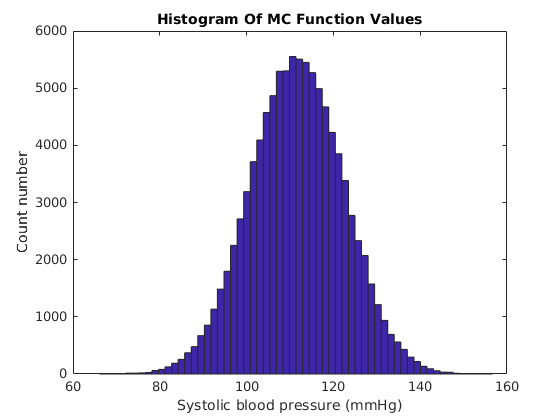

ylabel("Count number")
xlabel("Systolic blood pressure (mmHg)")

uncertMC = (CI(2)-CI(1))/2

uncertMC = 10.6911

valMC

valMC = 111.6307


% Computing 95% intervals
[CI95,valMC]=propUncertMC(f,{{a ua};{b,ub};{'Custom',PAT_data}},n,'mean','CI',0.95)

CI95 =    90.4041  132.7528


valMC = 111.6189

Excersize: repeat uncertainty quantification for the case when uncertainties in estimating coefficients are negligible: ub=ua=0.0001. What is the standard deviation and 95% confidence intervals in this case.

### Averaging the estimated over time

T=15; %averaging over T pulsees
uncertMC_T=uncertMC/sqrt(15)

uncertMC_T = 2.7604

### Example of calculating uncertainty subtraction of two uniform random variable

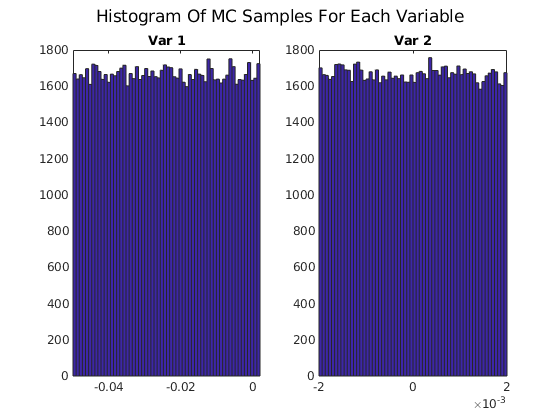

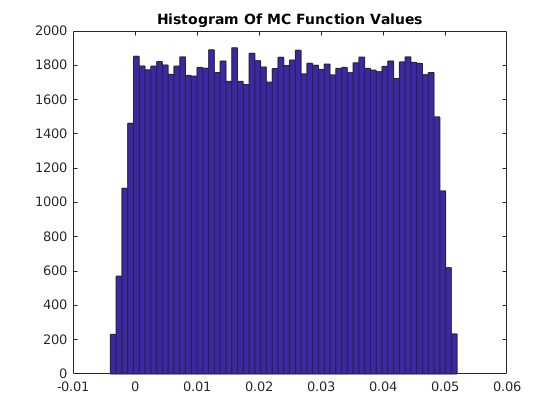

%Now truncate the distribution to prevent complex numbers.
f1 = @(x1,x2)x2-x1;
[CI,valMC]=propUncertMC(f1,{{'uniform',-0.05,0.002};{'uniform',-0.002,0.002}},n,'mean','varHist',60,'hist',60);

uncertMC = (CI(2)-CI(1))/2  % this is a triangular distribution and therefore this way of computing uncertianty is not valid

uncertMC = 0.0176

valMC

valMC = 0.0240